clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[5.827;2.870;11.960];
u31=[0.630;-0.496;0.598];
r2=[6.259;-2.258;19.135];
u32=[0.630;-0.496;0.598];
r3=[4.761;4.932;19.135];
u33=[0.630;-0.496;0.598];
r4=[7.573;7.125;8.770];
u34=[0.630;-0.496;0.598];
r5=[9.071;-0.065;8.770];
u35=[0.630;-0.496;0.598];
r6=[-1.081;-2.258;19.135];
u36=[0.630;-0.496;0.598];
r7=[-2.579;4.932;19.135];
u37=[0.630;-0.496;0.598];
r8=[0.233;7.125;8.770];
u38=[0.630;-0.496;0.598];
r9=[1.731;-0.065;8.770];
u39=[0.630;-0.496;0.598];
r10=[8.639;5.062;1.595];
u310=[0.630;-0.496;0.598];
r11=[-1.513;2.870;11.960];
u311=[0.630;-0.496;0.598];
r12=[4.329;10.060;11.960];
u312=[0.630;-0.496;0.598];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];
x10=[];
y10=[];
x11=[];
y11=[];

hold on 
axis([0 15 0 15]);
for R1=3:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.0000    7.3000    1.0001


ans =     3.3000    5.8000    1.0059


ans =     3.6000    5.1500    1.0059


ans =     3.9000    4.7500    1.0110


ans =     4.2000    4.5000    1.0127


ans =     4.5000    4.3500    1.0063


ans =     4.8000    4.2000    1.0137


ans =     5.1000    4.1000    1.0150


ans =     5.4000    4.0500    1.0052


ans =     5.7000    4.0000    1.0005


ans =     6.0000    3.9500    1.0000


ans =     6.3000    3.9000    1.0032


ans =     6.6000    3.8500    1.0096


ans =     6.9000    3.8000    1.0189


ans =     7.2000    3.8000    1.0072


ans =     7.5000    3.7500    1.0204


ans =     7.8000    3.7500    1.0112


ans =     8.1000    3.7500    1.0031


ans =     8.4000    3.7000    1.0203


ans =     8.7000    3.7000    1.0138


ans =     9.0000    3.7000    1.0079


ans =     9.3000    3.7000    1.0027


ans =     9.6000    3.6500    1.0234


ans =     9.9000    3.6500    1.0190


ans =    10.2000    3.6500    1.0151


ans =    10.5000    3.6500    1.0115


ans =    10.8000    3.6500    1.0082


ans =    11.1000    3.6500    1.0052


ans =    11.4000    3.6500    1.0024


ans =    11.7000    3.6000    1.0265


ans =    12.0000    3.6000    1.0242


ans =    12.3000    3.6000    1.0220


ans =    12.6000    3.6000    1.0200


ans =    12.9000    3.6000    1.0182



plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')

for R3=10:-0.3:1.7 %离心率
    R1=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =     3.5700   10.0000    1.0002


ans =     3.5700    9.7000    1.0012


ans =     3.5700    9.4000    1.0024


ans =     3.5700    9.1000    1.0037


ans =     3.5700    8.8000    1.0051


ans =     3.5800    8.5000    1.0012


ans =     3.5800    8.2000    1.0029


ans =     3.5800    7.9000    1.0048


ans =     3.5900    7.6000    1.0016


ans =     3.5900    7.3000    1.0040


ans =     3.6000    7.0000    1.0014


ans =     3.6000    6.7000    1.0045


ans =     3.6100    6.4000    1.0028


ans =     3.6200    6.1000    1.0016


ans =     3.6300    5.8000    1.0012


ans =     3.6400    5.5000    1.0016


ans = 1×3
    3.6500    5.2000    1.0030


ans = 1×3
    3.6700    4.9000    1.0006


ans = 1×3
    3.6900    4.6000    1.0000


ans = 1×3
    3.7100    4.3000    1.0016


ans = 1×3
    3.7400    4.0000    1.0013


ans = 1×3
    3.7800    3.7000    1.0002


ans = 1×3
    3.8300    3.4000    1.0001


ans = 1×3
    3.8900    3.1000    1.0035


ans = 1×3
    3.9900    2.8000    1.0022


ans = 1×3
    4.1400    2.5000    1.0009


ans = 1×3
    4.3800    2.2000    1.0016


ans = 1×3
    4.8500    1.9000    1.0002



for R1=5.4:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans = 1×3
    5.4000    1.7200    1.0006


ans = 1×3
    5.7000    1.6500    1.0063


ans = 1×3
    6.0000    1.6100    1.0003


ans = 1×3
    6.3000    1.5700    1.0020


ans = 1×3
    6.6000    1.5400    1.0013


ans = 1×3
    6.9000    1.5100    1.0060


ans = 1×3
    7.2000    1.4900    1.0051


ans = 1×3
    7.5000    1.4700    1.0076


ans = 1×3
    7.8000    1.4600    1.0021


ans = 1×3
    8.1000    1.4400    1.0100


ans = 1×3
    8.4000    1.4300    1.0087


ans = 1×3
    8.7000    1.4200    1.0091


ans = 1×3
    9.0000    1.4100    1.0110


ans = 1×3
    9.3000    1.4100    1.0018


ans = 1×3
    9.6000    1.4000    1.0060


ans = 1×3
    9.9000    1.3900    1.0113


ans = 1×3
   10.2000    1.3900    1.0046


ans = 1×3
   10.5000    1.3800    1.0116


ans = 1×3
   10.8000    1.3800    1.0062


ans = 1×3
   11.1000    1.3800    1.0013


ans = 1×3
   11.4000    1.3700    1.0103


ans = 1×3
   11.7000    1.3700    1.0063


ans = 1×3
   12.0000    1.3700    1.0027


ans = 1×3
   12.3000    1.3600    1.0133


ans = 1×3
   12.6000    1.3600    1.0104


ans = 1×3
   12.9000    1.3600    1.0078



plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')

for R3=10:-0.3:2.5 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    2.4100   10.0000    1.0034


ans = 1×3
    2.4100    9.7000    1.0047


ans = 1×3
    2.4100    9.4000    1.0062


ans = 1×3
    2.4100    9.1000    1.0078


ans = 1×3
    2.4200    8.8000    1.0015


ans = 1×3
    2.4200    8.5000    1.0034


ans = 1×3
    2.4200    8.2000    1.0056


ans = 1×3
    2.4300    7.9000    1.0001


ans = 1×3
    2.4300    7.6000    1.0028


ans = 1×3
    2.4300    7.3000    1.0059


ans = 1×3
    2.4400    7.0000    1.0015


ans = 1×3
    2.4400    6.7000    1.0055


ans = 1×3
    2.4500    6.4000    1.0022


ans = 1×3
    2.4500    6.1000    1.0075


ans = 1×3
    2.4600    5.8000    1.0058


ans = 1×3
    2.4700    5.5000    1.0053


ans = 1×3
    2.4800    5.2000    1.0061


ans = 1×3
    2.5000    4.9000    1.0013


ans = 1×3
    2.5100    4.6000    1.0060


ans = 1×3
    2.5300    4.3000    1.0062


ans = 1×3
    2.5600    4.0000    1.0034


ans = 1×3
    2.5900    3.7000    1.0058


ans = 1×3
    2.6400    3.4000    1.0025


ans = 1×3
    2.7000    3.1000    1.0039


ans = 1×3
    2.7900    2.8000    1.0043


ans = 1×3
    2.9400    2.5000    1.0005


%将曲线完善
for R1=2.7:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    2.7000    3.1200    1.0011


ans = 1×3
    3.0000    2.4100    1.0003


ans = 1×3
    3.3000    2.1100    1.0020


ans = 1×3
    3.6000    1.9500    1.0002


ans = 1×3
    3.9000    1.8400    1.0042


ans = 1×3
    4.2000    1.7700    1.0035


ans = 1×3
    4.5000    1.7200    1.0022


ans = 1×3
    4.8000    1.6800    1.0031


ans = 1×3
    5.1000    1.6500    1.0028


ans = 1×3
    5.4000    1.6200    1.0087


ans = 1×3
    5.7000    1.6000    1.0095


ans = 1×3
    6.0000    1.5900    1.0032


ans = 1×3
    6.3000    1.5700    1.0106


ans = 1×3
    6.6000    1.5600    1.0094


ans = 1×3
    6.9000    1.5500    1.0100


ans = 1×3
    7.2000    1.5500    1.0007


ans = 1×3
    7.5000    1.5400    1.0042


ans = 1×3
    7.8000    1.5300    1.0089


ans = 1×3
    8.1000    1.5300    1.0026


ans = 1×3
    8.4000    1.5200    1.0092


ans = 1×3
    8.7000    1.5200    1.0042


ans = 1×3
    9.0000    1.5100    1.0123


ans = 1×3
    9.3000    1.5100    1.0084


ans = 1×3
    9.6000    1.5100    1.0050


ans = 1×3
    9.9000    1.5100    1.0019


ans = 1×3
   10.2000    1.5000    1.0120


ans = 1×3
   10.5000    1.5000    1.0096


ans = 1×3
   10.8000    1.5000    1.0075


ans = 1×3
   11.1000    1.5000    1.0056


ans = 1×3
   11.4000    1.5000    1.0040


ans = 1×3
   11.7000    1.5000    1.0025


ans = 1×3
   12.0000    1.5000    1.0013


ans = 1×3
   12.3000    1.5000    1.0002


ans = 1×3
   12.6000    1.4900    1.0125


ans = 1×3
   12.9000    1.4900    1.0117



plot(x3,y3,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')

for R3=1:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
    4.2900    1.0000    1.0000


ans = 1×3
    3.2700    1.3000    1.0014


ans = 1×3
    2.9800    1.6000    1.0015


ans = 1×3
    2.8400    1.9000    1.0056


ans = 1×3
    2.7700    2.2000    1.0034


ans = 1×3
    2.7200    2.5000    1.0063


ans = 1×3
    2.6900    2.8000    1.0060


ans = 1×3
    2.6700    3.1000    1.0051


ans = 1×3
    2.6600    3.4000    1.0010


ans = 1×3
    2.6400    3.7000    1.0069


ans = 1×3
    2.6400    4.0000    1.0002


ans = 1×3
    2.6300    4.3000    1.0022


ans = 1×3
    2.6200    4.6000    1.0053


ans = 1×3
    2.6200    4.9000    1.0017


ans = 1×3
    2.6100    5.2000    1.0062


ans = 1×3
    2.6100    5.5000    1.0038


ans = 1×3
    2.6100    5.8000    1.0017


ans = 1×3
    2.6000    6.1000    1.0074


ans = 1×3
    2.6000    6.4000    1.0059


ans = 1×3
    2.6000    6.7000    1.0045


ans = 1×3
    2.6000    7.0000    1.0033


ans = 1×3
    2.6000    7.3000    1.0023


ans = 1×3
    2.6000    7.6000    1.0014


ans = 1×3
    2.6000    7.9000    1.0005


ans = 1×3
    2.5900    8.2000    1.0075


ans = 1×3
    2.5900    8.5000    1.0068


ans = 1×3
    2.5900    8.8000    1.0062


ans = 1×3
    2.5900    9.1000    1.0057


ans = 1×3
    2.5900    9.4000    1.0052


ans = 1×3
    2.5900    9.7000    1.0048


ans = 1×3
    2.5900   10.0000    1.0044



plot(x4,y4,'color',[239, 193, 48]/256, ...
    'LineWidth',1.5,'DisplayName','1-5')

for R3=10:-0.3:2.8 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    5.5000   10.0000    1.0017


ans = 1×3
    5.5000    9.7000    1.0026


ans = 1×3
    5.5100    9.4000    1.0001


ans = 1×3
    5.5100    9.1000    1.0013


ans = 1×3
    5.5100    8.8000    1.0026


ans = 1×3
    5.5200    8.5000    1.0004


ans = 1×3
    5.5200    8.2000    1.0020


ans = 1×3
    5.5300    7.9000    1.0003


ans = 1×3
    5.5300    7.6000    1.0023


ans = 1×3
    5.5400    7.3000    1.0010


ans = 1×3
    5.5400    7.0000    1.0035


ans = 1×3
    5.5500    6.7000    1.0029


ans = 1×3
    5.5600    6.4000    1.0027


ans = 1×3
    5.5700    6.1000    1.0030


ans = 1×3
    5.5900    5.8000    1.0005


ans = 1×3
    5.6000    5.5000    1.0023


ans = 1×3
    5.6200    5.2000    1.0015


ans = 1×3
    5.6400    4.9000    1.0020


ans = 1×3
    5.6700    4.6000    1.0008


ans = 1×3
    5.7000    4.3000    1.0016


ans = 1×3
    5.7400    4.0000    1.0018


ans = 1×3
    5.7900    3.7000    1.0025


ans = 1×3
    5.8600    3.4000    1.0021


ans = 1×3
    5.9600    3.1000    1.0002


ans = 1×3
    6.0900    2.8000    1.0010



for R1=6:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    6.0000    2.9900    1.0011


ans = 1×3
    6.3000    2.4900    1.0004


ans = 1×3
    6.6000    2.2100    1.0008


ans = 1×3
    6.9000    2.0300    1.0013


ans = 1×3
    7.2000    1.9000    1.0035


ans = 1×3
    7.5000    1.8100    1.0024


ans = 1×3
    7.8000    1.7400    1.0015


ans = 1×3
    8.1000    1.6800    1.0035


ans = 1×3
    8.4000    1.6300    1.0063


ans = 1×3
    8.7000    1.6000    1.0002


ans = 1×3
    9.0000    1.5600    1.0064


ans = 1×3
    9.3000    1.5400    1.0003


ans = 1×3
    9.6000    1.5100    1.0060


ans = 1×3
    9.9000    1.4900    1.0058


ans = 1×3
   10.2000    1.4700    1.0082


ans = 1×3
   10.5000    1.4600    1.0026


ans = 1×3
   10.8000    1.4400    1.0092


ans = 1×3
   11.1000    1.4300    1.0069


ans = 1×3
   11.4000    1.4200    1.0060


ans = 1×3
   11.7000    1.4100    1.0064


ans = 1×3
   12.0000    1.4000    1.0079


ans = 1×3
   12.3000    1.3900    1.0105


ans = 1×3
   12.6000    1.3900    1.0021


ans = 1×3
   12.9000    1.3800    1.0064



plot(x5,y5,'color',[151, 150, 159]/256, ...
    'LineWidth',1.5,'DisplayName','1-6')

for R3=1.6:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];  
end

ans = 1×3
    7.1500    1.6000    1.0015


ans = 1×3
    6.5400    1.9000    1.0003


ans = 1×3
    6.2300    2.2000    1.0004


ans = 1×3
    6.0400    2.5000    1.0026


ans = 1×3
    5.9300    2.8000    1.0006


ans = 1×3
    5.8500    3.1000    1.0003


ans = 1×3
    5.7900    3.4000    1.0009


ans = 1×3
    5.7400    3.7000    1.0030


ans = 1×3
    5.7100    4.0000    1.0019


ans = 1×3
    5.6800    4.3000    1.0032


ans = 1×3
    5.6600    4.6000    1.0028


ans = 1×3
    5.6500    4.9000    1.0005


ans = 1×3
    5.6300    5.2000    1.0025


ans = 1×3
    5.6200    5.5000    1.0019


ans = 1×3
    5.6100    5.8000    1.0019


ans = 1×3
    5.6000    6.1000    1.0024


ans = 1×3
    5.5900    6.4000    1.0034


ans = 1×3
    5.5900    6.7000    1.0012


ans = 1×3
    5.5800    7.0000    1.0028


ans = 1×3
    5.5800    7.3000    1.0011


ans = 1×3
    5.5700    7.6000    1.0031


ans = 1×3
    5.5700    7.9000    1.0018


ans = 1×3
    5.5700    8.2000    1.0006


ans = 1×3
    5.5600    8.5000    1.0031


ans = 1×3
    5.5600    8.8000    1.0022


ans = 1×3
    5.5600    9.1000    1.0013


ans = 1×3
    5.5600    9.4000    1.0005


ans = 1×3
    5.5500    9.7000    1.0034


ans = 1×3
    5.5500   10.0000    1.0027



plot(x6,y6,'color',[237, 125, 49]/256, ...
    'LineWidth',1.5,'DisplayName','1-7')

for R1=1.3:0.3:13 %离心率
    R3=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];  
end

ans = 1×3
    1.3000    4.8600    1.0015


ans = 1×3
    1.6000    4.3900    1.0015


ans = 1×3
    1.9000    4.1800    1.0007


ans = 1×3
    2.2000    4.0600    1.0020


ans = 1×3
    2.5000    3.9900    1.0010


ans = 1×3
    2.8000    3.9400    1.0019


ans = 1×3
    3.1000    3.9100    1.0002


ans = 1×3
    3.4000    3.8800    1.0028


ans = 1×3
    3.7000    3.8600    1.0036


ans = 1×3
    4.0000    3.8500    1.0015


ans = 1×3
    4.3000    3.8400    1.0008


ans = 1×3
    4.6000    3.8300    1.0013


ans = 1×3
    4.9000    3.8200    1.0026


ans = 1×3
    5.2000    3.8100    1.0047


ans = 1×3
    5.5000    3.8100    1.0021


ans = 1×3
    5.8000    3.8000    1.0050


ans = 1×3
    6.1000    3.8000    1.0032


ans = 1×3
    6.4000    3.8000    1.0016


ans = 1×3
    6.7000    3.8000    1.0002


ans = 1×3
    7.0000    3.7900    1.0042


ans = 1×3
    7.3000    3.7900    1.0032


ans = 1×3
    7.6000    3.7900    1.0023


ans = 1×3
    7.9000    3.7900    1.0015


ans = 1×3
    8.2000    3.7900    1.0008


ans = 1×3
    8.5000    3.7900    1.0002


ans = 1×3
    8.8000    3.7800    1.0049


ans = 1×3
    9.1000    3.7800    1.0045


ans = 1×3
    9.4000    3.7800    1.0041


ans = 1×3
    9.7000    3.7800    1.0037


ans = 1×3
   10.0000    3.7800    1.0034


ans = 1×3
   10.3000    3.7800    1.0031


ans = 1×3
   10.6000    3.7800    1.0029


ans = 1×3
   10.9000    3.7800    1.0027


ans = 1×3
   11.2000    3.7800    1.0025


ans = 1×3
   11.5000    3.7800    1.0023


ans = 1×3
   11.8000    3.7800    1.0022


ans = 1×3
   12.1000    3.7800    1.0021


ans = 1×3
   12.4000    3.7800    1.0020


ans = 1×3
   12.7000    3.7800    1.0019


ans = 1×3
   13.0000    3.7800    1.0019



plot(x7,y7,'color',[47, 85, 151]/256, ...
    'LineWidth',1.5,'DisplayName','1-8')

for R3=10:-0.3:2.2 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];  
end

ans = 1×3
    2.5900   10.0000    1.0059


ans = 1×3
    2.5900    9.7000    1.0074


ans = 1×3
    2.6000    9.4000    1.0014


ans = 1×3
    2.6000    9.1000    1.0031


ans = 1×3
    2.6000    8.8000    1.0051


ans = 1×3
    2.6000    8.5000    1.0072


ans = 1×3
    2.6100    8.2000    1.0021


ans = 1×3
    2.6100    7.9000    1.0048


ans = 1×3
    2.6200    7.6000    1.0003


ans = 1×3
    2.6200    7.3000    1.0037


ans = 1×3
    2.6300    7.0000    1.0002


ans = 1×3
    2.6300    6.7000    1.0045


ans = 1×3
    2.6400    6.4000    1.0022


ans = 1×3
    2.6500    6.1000    1.0007


ans = 1×3
    2.6600    5.8000    1.0002


ans = 1×3
    2.6700    5.5000    1.0009


ans = 1×3
    2.6800    5.2000    1.0030


ans = 1×3
    2.7000    4.9000    1.0002


ans = 1×3
    2.7100    4.6000    1.0064


ans = 1×3
    2.7400    4.3000    1.0025


ans = 1×3
    2.7700    4.0000    1.0030


ans = 1×3
    2.8100    3.7000    1.0029


ans = 1×3
    2.8600    3.4000    1.0049


ans = 1×3
    2.9400    3.1000    1.0020


ans = 1×3
    3.0500    2.8000    1.0020


ans = 1×3
    3.2200    2.5000    1.0037


ans = 1×3
    3.5400    2.2000    1.0012



for R1=4:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];  
end

ans = 1×3
    4.0000    1.9700    1.0048


ans = 1×3
    4.3000    1.8900    1.0007


ans = 1×3
    4.6000    1.8200    1.0064


ans = 1×3
    4.9000    1.7800    1.0012


ans = 1×3
    5.2000    1.7400    1.0045


ans = 1×3
    5.5000    1.7100    1.0058


ans = 1×3
    5.8000    1.6900    1.0029


ans = 1×3
    6.1000    1.6700    1.0039


ans = 1×3
    6.4000    1.6500    1.0082


ans = 1×3
    6.7000    1.6400    1.0049


ans = 1×3
    7.0000    1.6300    1.0035


ans = 1×3
    7.3000    1.6200    1.0038


ans = 1×3
    7.6000    1.6100    1.0057


ans = 1×3
    7.9000    1.6000    1.0089


ans = 1×3
    8.2000    1.6000    1.0017


ans = 1×3
    8.5000    1.5900    1.0069


ans = 1×3
    8.8000    1.5900    1.0013


ans = 1×3
    9.1000    1.5800    1.0080


ans = 1×3
    9.4000    1.5800    1.0035


ans = 1×3
    9.7000    1.5700    1.0115


ans = 1×3
   10.0000    1.5700    1.0080


ans = 1×3
   10.3000    1.5700    1.0048


ans = 1×3
   10.6000    1.5700    1.0020


ans = 1×3
   10.9000    1.5600    1.0117


ans = 1×3
   11.2000    1.5600    1.0095


ans = 1×3
   11.5000    1.5600    1.0075


ans = 1×3
   11.8000    1.5600    1.0057


ans = 1×3
   12.1000    1.5600    1.0041


ans = 1×3
   12.4000    1.5600    1.0028


ans = 1×3
   12.7000    1.5600    1.0015


ans = 1×3
   13.0000    1.5600    1.0005



plot(x8,y8,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-9')

for R1=5:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x9=[x9,R1];
    y9=[y9,R3];  
end

ans = 1×3
    5.0000    8.6000    1.0002


ans = 1×3
    5.3000    6.1400    1.0003


ans = 1×3
    5.6000    5.1600    1.0009


ans = 1×3
    5.9000    4.6200    1.0006


ans = 1×3
    6.2000    4.2700    1.0006


ans = 1×3
    6.5000    4.0200    1.0015


ans = 1×3
    6.8000    3.8400    1.0009


ans = 1×3
    7.1000    3.7000    1.0006


ans = 1×3
    7.4000    3.5800    1.0032


ans = 1×3
    7.7000    3.4900    1.0029


ans = 1×3
    8.0000    3.4200    1.0010


ans = 1×3
    8.3000    3.3500    1.0037


ans = 1×3
    8.6000    3.3000    1.0022


ans = 1×3
    8.9000    3.2500    1.0039


ans = 1×3
    9.2000    3.2100    1.0039


ans = 1×3
    9.5000    3.1800    1.0016


ans = 1×3
    9.8000    3.1500    1.0012


ans = 1×3
   10.1000    3.1200    1.0025


ans = 1×3
   10.4000    3.1000    1.0003


ans = 1×3
   10.7000    3.0700    1.0046


ans = 1×3
   11.0000    3.0500    1.0049


ans = 1×3
   11.3000    3.0400    1.0007


ans = 1×3
   11.6000    3.0200    1.0029


ans = 1×3
   11.9000    3.0100    1.0004


ans = 1×3
   12.2000    2.9900    1.0042


ans = 1×3
   12.5000    2.9800    1.0030


ans = 1×3
   12.8000    2.9700    1.0024



plot(x9,y9,'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'DisplayName','1-10')

for R3=10:-0.3:3 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r11,R1,R3,u31,u311);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    [R1,R3,miu2]
    x10=[x10,R1];
    y10=[y10,R3];  
end

ans = 1×3
    2.9200   10.0000    1.0063


ans = 1×3
    2.9300    9.7000    1.0032


ans = 1×3
    2.9400    9.4000    1.0004


ans = 1×3
    2.9400    9.1000    1.0045


ans = 1×3
    2.9500    8.8000    1.0026


ans = 1×3
    2.9600    8.5000    1.0012


ans = 1×3
    2.9700    8.2000    1.0005


ans = 1×3
    2.9800    7.9000    1.0005


ans = 1×3
    2.9900    7.6000    1.0013


ans = 1×3
    3.0000    7.3000    1.0030


ans = 1×3
    3.0100    7.0000    1.0058


ans = 1×3
    3.0300    6.7000    1.0040


ans = 1×3
    3.0500    6.4000    1.0038


ans = 1×3
    3.0800    6.1000    1.0000


ans = 1×3
    3.1000    5.8000    1.0043


ans = 1×3
    3.1400    5.5000    1.0007


ans = 1×3
    3.1800    5.2000    1.0010


ans = 1×3
    3.2300    4.9000    1.0013


ans = 1×3
    3.2900    4.6000    1.0031


ans = 1×3
    3.3800    4.3000    1.0002


ans = 1×3
    3.4900    4.0000    1.0010


ans = 1×3
    3.6500    3.7000    1.0002


ans = 1×3
    3.8800    3.4000    1.0020


ans = 1×3
    4.2700    3.1000    1.0019



for R1=4:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r11,R1,R3,u31,u311);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    [R1,R3,miu2]
    x10=[x10,R1];
    y10=[y10,R3];  
end

ans = 1×3
    4.0000    3.2900    1.0016


ans = 1×3
    4.3000    3.0800    1.0029


ans = 1×3
    4.6000    2.9400    1.0025


ans = 1×3
    4.9000    2.8400    1.0013


ans = 1×3
    5.2000    2.7600    1.0025


ans = 1×3
    5.5000    2.7000    1.0023


ans = 1×3
    5.8000    2.6500    1.0033


ans = 1×3
    6.1000    2.6100    1.0038


ans = 1×3
    6.4000    2.5800    1.0023


ans = 1×3
    6.7000    2.5500    1.0042


ans = 1×3
    7.0000    2.5300    1.0022


ans = 1×3
    7.3000    2.5100    1.0024


ans = 1×3
    7.6000    2.4900    1.0045


ans = 1×3
    7.9000    2.4800    1.0012


ans = 1×3
    8.2000    2.4600    1.0063


ans = 1×3
    8.5000    2.4500    1.0054


ans = 1×3
    8.8000    2.4400    1.0054


ans = 1×3
    9.1000    2.4300    1.0063


ans = 1×3
    9.4000    2.4300    1.0003


ans = 1×3
    9.7000    2.4200    1.0025


ans = 1×3
   10.0000    2.4100    1.0053


ans = 1×3
   10.3000    2.4100    1.0009


ans = 1×3
   10.6000    2.4000    1.0046


ans = 1×3
   10.9000    2.4000    1.0010


ans = 1×3
   11.2000    2.3900    1.0055


ans = 1×3
   11.5000    2.3900    1.0025


ans = 1×3
   11.8000    2.3800    1.0077


ans = 1×3
   12.1000    2.3800    1.0051


ans = 1×3
   12.4000    2.3800    1.0028


ans = 1×3
   12.7000    2.3800    1.0007


ans = 1×3
   13.0000    2.3700    1.0068


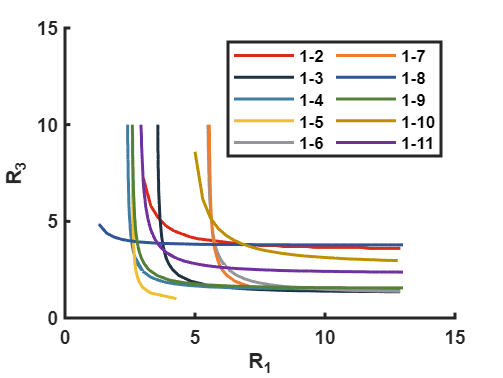


plot(x10,y10,'color',[112, 48, 160]/256, ...
    'LineWidth',1.5,'DisplayName','1-11')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
